# 2.1 采样定理：采样、频谱周期延拓与混叠、用内插公式恢复

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。 图和核验数据写入同目录 results。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');   % 由 build_mlx 设置：Live Script 里每格单独一张图；普通运行时拼成一张图存 PNG
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：同一个 5 Hz 正弦，采样率够与不够

预测：f_s = 50 Hz 和 6 Hz 采出来的点，哪一组还能看出是 5 Hz？6 Hz 采出来像几 Hz？

f0 = 5; dur = 1; tc = 0:1e-4:dur; xa = @(t) cos(2*pi*f0*t);
fsHigh = 50; nH = 0:fsHigh*dur; tH = nH/fsHigh; xH = xa(tH);
fsLow = 6;   nL = 0:fsLow*dur;  tL = nL/fsLow;  xL = xa(tL);
fAlias = abs(f0 - fsLow);                          % 折叠后的表观频率：|5 − 6| = 1 Hz

## 演示2：频谱周期延拓——采样率 20 Hz 不重叠，12 Hz 重叠（混叠）

信号含 2、5、8 Hz 三个分量（最高 8 Hz）；采样后频谱以 f_s 为周期重复。

tones = [2 5 8]; amps = [1 0.8 0.6];
fsA = 20; fsB = 12;                                % 20 ≥ 2×8 不混叠；12 < 16 混叠
spectrumLines = @(fs) reshape((-3:3)'*fs + [tones, -tones], 1, []);   % 每个副本的谱线位置
lineAmps = @(fs) repelem([amps, amps], 7);        % 与 spectrumLines 的列主序一致

## 演示3：从样本恢复连续信号——内插公式（教材 2.1.2）

x_a(t) = Σ x(n) sin(π(t−nT)/T) / (π(t−nT)/T)，用 f_s = 12 Hz 的样本恢复 5 Hz 正弦。

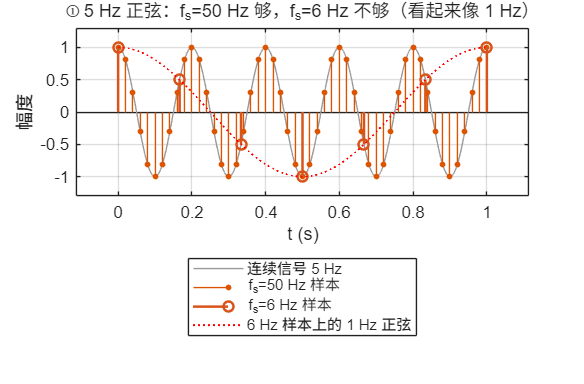

fsR = 12; T = 1/fsR; nR = -60:60; tR = nR*T; xR = xa(tR);   % 多取一些样本，减小截断影响
sincU = @(z) (z == 0) + (z ~= 0).*sin(z + (z == 0))./(z + (z == 0));
tq = 0:1e-3:dur;
xRec = zeros(size(tq));
for k = 1:numel(nR), xRec = xRec + xR(k)*sincU(pi*(tq - tR(k))/T); end
xZoh = interp1(tR, xR, tq, 'previous');            % 零阶保持对照
xLin = interp1(tR, xR, tq, 'linear');              % 线性内插对照
errSinc = max(abs(xRec - xa(tq))); errZoh = max(abs(xZoh - xa(tq))); errLin = max(abs(xLin - xa(tq)));
% 混叠情形：用 6 Hz 的样本做同样的内插，只能恢复出 1 Hz
T6 = 1/fsLow; n6 = -30:30; t6 = n6*T6; x6 = xa(t6); xRec6 = zeros(size(tq));
for k = 1:numel(n6), xRec6 = xRec6 + x6(k)*sincU(pi*(tq - t6(k))/T6); end

if ~LIVE, f1 = figure('Name','01 采样定理','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(tc, xa(tc), 'Color', [0.6 0.6 0.6]); hold on;
stem(tH, xH, 'filled', 'MarkerSize', 3); stem(tL, xL, 'MarkerSize', 6, 'LineWidth', 1.5, 'Color', [0.85 0.33 0.1]);
plot(tc, cos(2*pi*fAlias*tc), 'r:', 'LineWidth', 1.2); grid on; ylim([-1.3 1.3]);
title(sprintf('① 5 Hz 正弦：f_s=%d Hz 够，f_s=%d Hz 不够（看起来像 %g Hz）', fsHigh, fsLow, fAlias)); xlabel('t (s)'); ylabel('幅度');
legend('连续信号 5 Hz','f_s=50 Hz 样本','f_s=6 Hz 样本','6 Hz 样本上的 1 Hz 正弦');

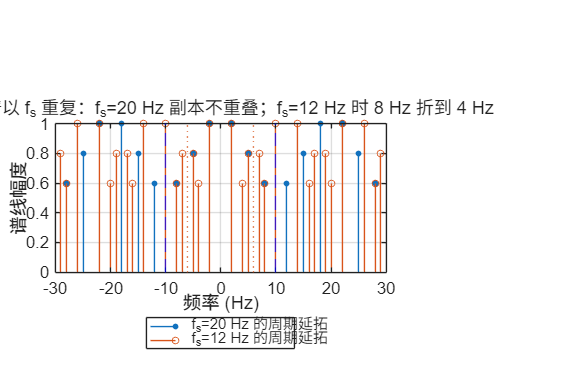

newpanel(); stem(spectrumLines(fsA), lineAmps(fsA), 'filled', 'MarkerSize', 3); hold on;
stem(spectrumLines(fsB), lineAmps(fsB), 'MarkerSize', 4, 'Color', [0.85 0.33 0.1]); grid on; xlim([-30 30]);
xline([-fsA/2 fsA/2], 'b--'); xline([-fsB/2 fsB/2], ':', 'Color', [0.85 0.33 0.1]);
title(sprintf('② 频谱以 f_s 重复：f_s=%d Hz 副本不重叠；f_s=%d Hz 时 8 Hz 折到 %d Hz', fsA, fsB, fsB-8));
xlabel('频率 (Hz)'); ylabel('谱线幅度'); legend('f_s=20 Hz 的周期延拓','f_s=12 Hz 的周期延拓');

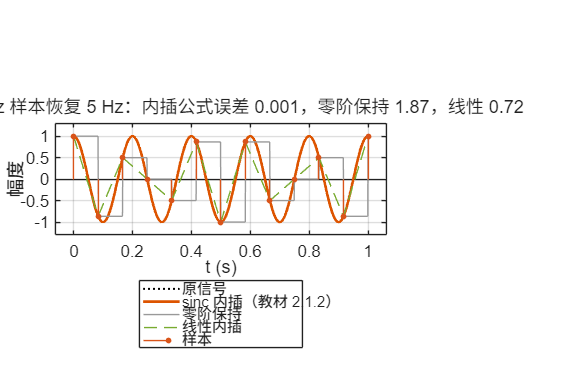

newpanel(); plot(tq, xa(tq), 'k:', 'LineWidth', 1.2); hold on;
plot(tq, xRec, 'LineWidth', 1.6); plot(tq, xZoh, 'Color', [0.6 0.6 0.6]); plot(tq, xLin, '--', 'Color', [0.47 0.67 0.19]);
stem(tR(tR >= 0 & tR <= dur), xR(tR >= 0 & tR <= dur), 'filled', 'MarkerSize', 3, 'Color', [0.85 0.33 0.1]); grid on; ylim([-1.3 1.3]);
title(sprintf('③ f_s=12 Hz 样本恢复 5 Hz：内插公式误差 %.3f，零阶保持 %.2f，线性 %.2f', errSinc, errZoh, errLin));
xlabel('t (s)'); ylabel('幅度'); legend('原信号','sinc 内插（教材 2.1.2）','零阶保持','线性内插','样本');

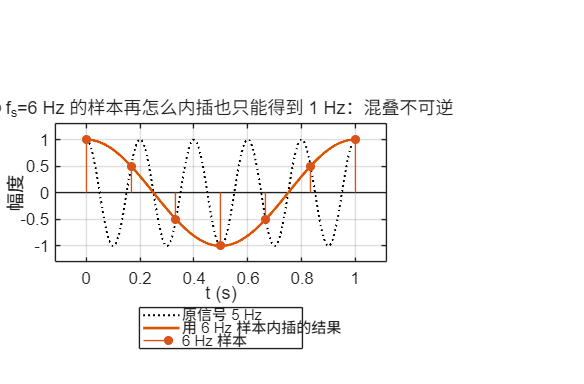

newpanel(); plot(tq, xa(tq), 'k:', 'LineWidth', 1.2); hold on; plot(tq, xRec6, 'LineWidth', 1.6);
stem(t6(t6 >= 0 & t6 <= dur), x6(t6 >= 0 & t6 <= dur), 'filled', 'MarkerSize', 5, 'Color', [0.85 0.33 0.1]); grid on; ylim([-1.3 1.3]);
title('④ f_s=6 Hz 的样本再怎么内插也只能得到 1 Hz：混叠不可逆'); xlabel('t (s)'); ylabel('幅度');
legend('原信号 5 Hz','用 6 Hz 样本内插的结果','6 Hz 样本');

if ~LIVE, sgtitle('采样定理：f_s 至少是最高频率的两倍；够了能用内插公式恢复，不够就混叠'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '01-sampling.png'), 'Resolution', 150); end

## 教师核验

assert(max(abs(xL - cos(2*pi*fAlias*tL))) < 1e-12, '6 Hz 样本应与 1 Hz 正弦逐点重合');
A = [cos(2*pi*fAlias*tq)', sin(2*pi*fAlias*tq)']; c = A \ xRec6'; ampAlias = hypot(c(1), c(2));
assert(abs(ampAlias - 1) < 0.05, '混叠情形内插结果应为幅度 1 的 1 Hz 正弦');
assert(errSinc < 0.02 && errZoh > 0.5 && errLin > 0.2, '内插误差关系不符合预期');
slB = spectrumLines(fsB); overlapB = max(slB(slB > 0 & slB < fsB/2 & ~ismember(slB, tones)));
assert(isequal(overlapB, fsB - 8), '12 Hz 采样时 8 Hz 应折到 4 Hz');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'tone_hz', f0, 'fs_high', fsHigh, 'fs_low', fsLow, 'alias_hz', fAlias, 'alias_fitted_amplitude', ampAlias, ...
    'tones_hz', tones, 'fs_no_overlap', fsA, 'fs_overlap', fsB, 'folded_8hz_to', fsB - 8, ...
    'fs_recover', fsR, 'sinc_max_error', errSinc, 'zoh_max_error', errZoh, 'linear_max_error', errLin, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-sampling.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

            matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                    run_at: '2026-09-18 19:30:14'
                   tone_hz: 5
                   fs_high: 50
                    fs_low: 6
                  alias_hz: 1
    alias_fitted_amplitude: 1.0003
                  tones_hz: [2 5 8]
             fs_no_overlap: 20
                fs_overlap: 12
             folded_8hz_to: 4
                fs_recover: 12
            sinc_max_error: 7.8677e-04
             zoh_max_error: 1.8655
          linear_max_error: 0.7183
         all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end